clear;
clc;
bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';
%bode_plot_options.PhaseWrapping = 'on';

# Plant

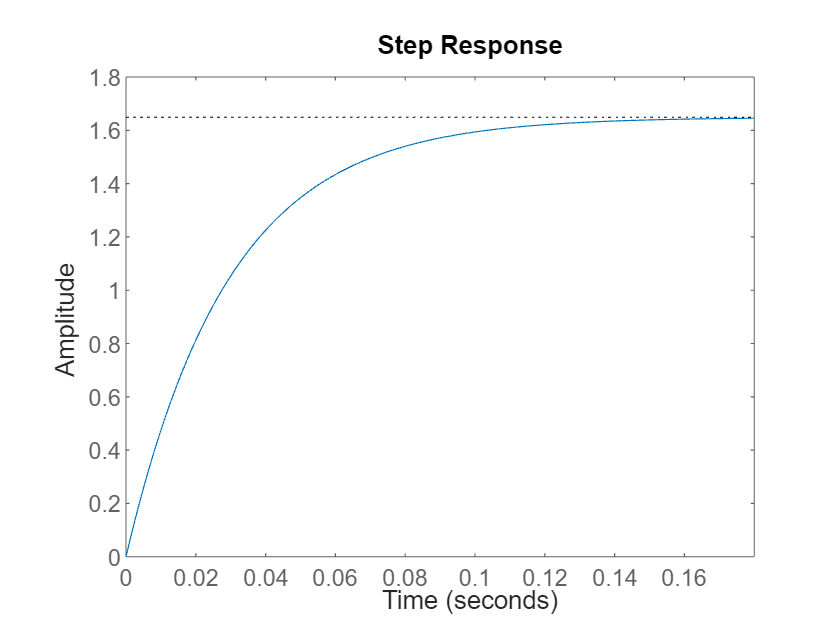

s = tf('s');
plant_tf = 55.99/(s+33.95);
step_response_parameters = stepinfo(plant_tf);
plant_tr = step_response_parameters.RiseTime;
step(plant_tf);

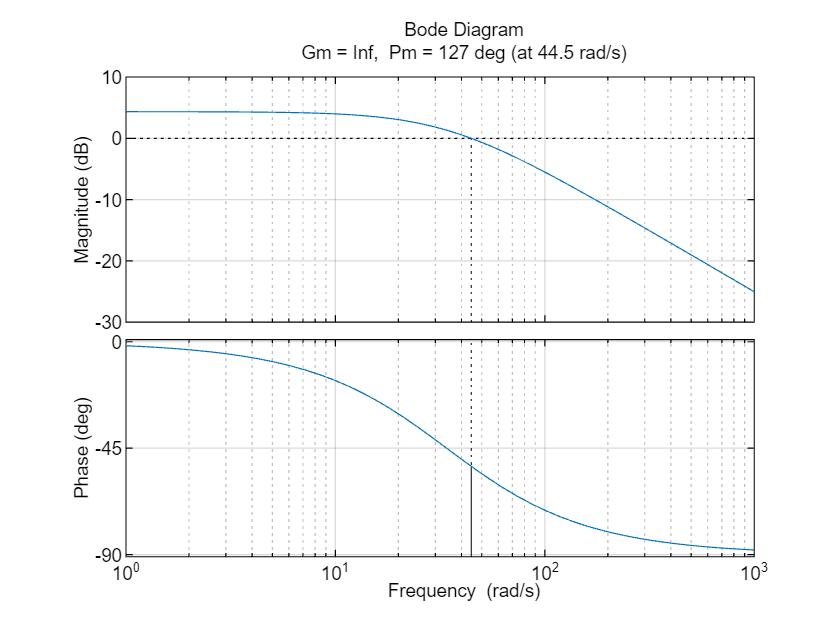

margin(plant_tf,bode_plot_options);

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0, Pm >= 40°, Gm>=10dB

Controller type: 2 integrators and 2 lead compensators

## Integrators

2 integrators are assigned to get Ev=0, K is set to lower the negative phase margin and allow the lead compensators to fix the inestability created by the double integrators,

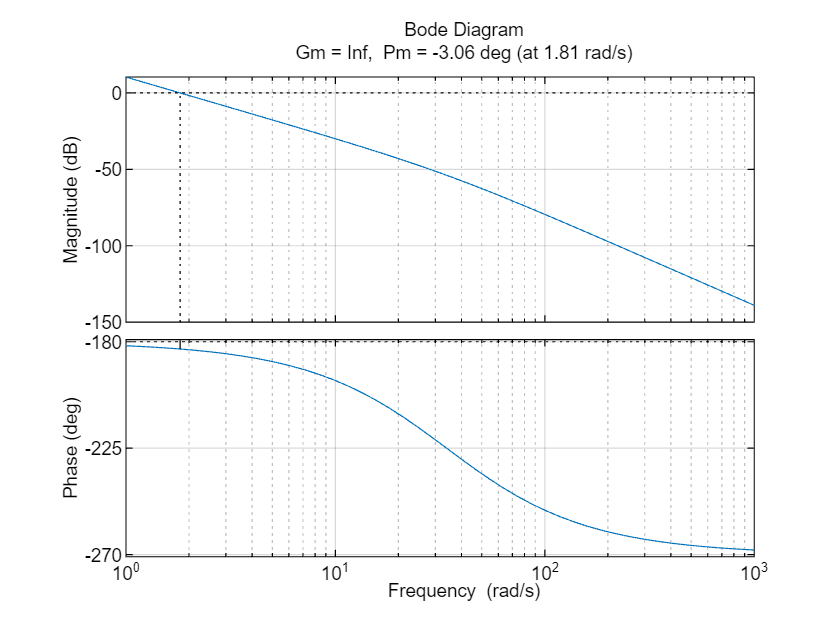

s = tf('s');
k =2;
integ_ctrl_tf = k/((s)^2);
integ_ctrl_plant_tf = series(integ_ctrl_tf,plant_tf);
margin(integ_ctrl_plant_tf,bode_plot_options);

## Lead Compensator

#### Parameters

required_pm1 = 50+25-(-3.06);
b_1 = (1 + sind(required_pm1))/(1-sind(required_pm1));
disp("w1_crossover_gain: " + num2str(-10*log(b_1)));

w1_crossover_gain: -45.157


#### Calculation

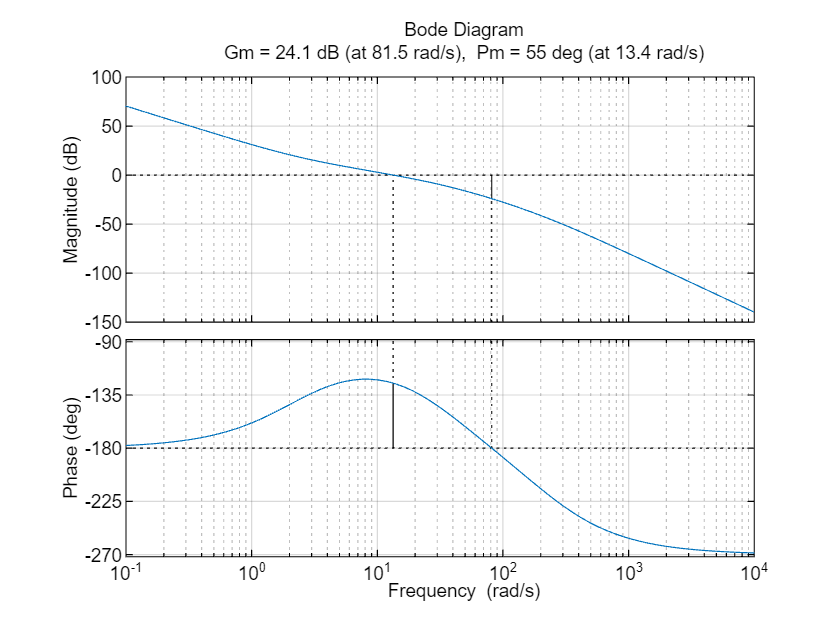

w1_crossover = 22.22;
T2_1=1/(sqrt(b_1)*w1_crossover);
k1 =10;
lead_ctrl_tf = k1*(1+(b_1*T2_1*s))/(1+(T2_1*s));
margin(lead_ctrl_tf*integ_ctrl_plant_tf,bode_plot_options);

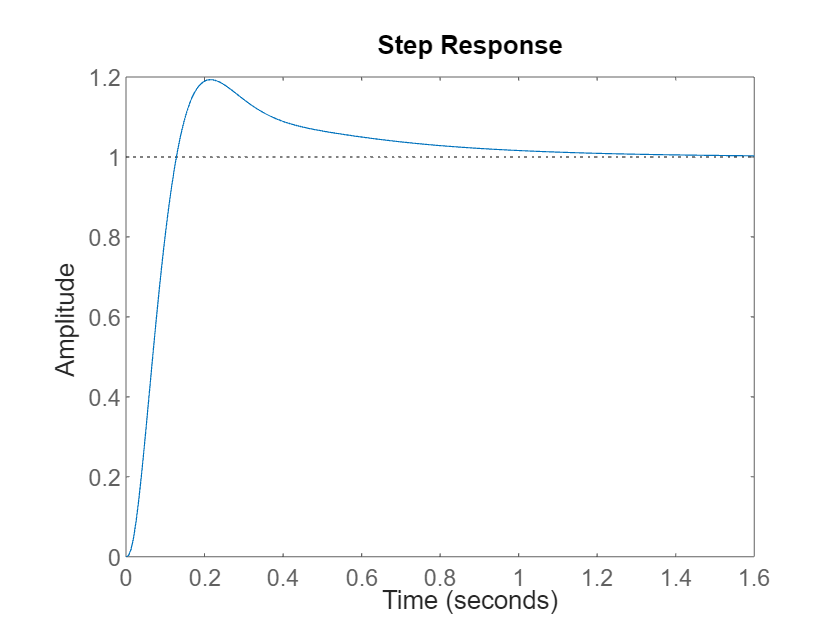

step(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1));

disp(stepinfo(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1)));

         RiseTime: 0.0853
    TransientTime: 0.9238
     SettlingTime: 0.9238
      SettlingMin: 0.9266
      SettlingMax: 1.1933
        Overshoot: 19.3347
       Undershoot: 0
             Peak: 1.1933
         PeakTime: 0.2132



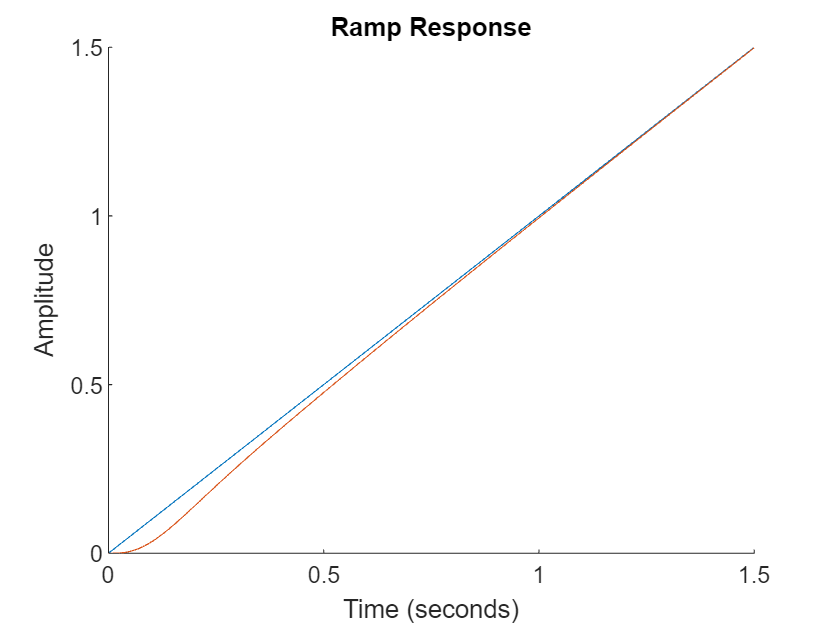

figure;
hold on;
t=0:0.005:1.5;
ramp=t;
[y,t]=lsim(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1),ramp,t);
plot(t,t);
plot(t,y);
title('Ramp Response');
xlabel('Time (seconds)');
ylabel('Amplitude');

## Discretization 

#### Plant

Ts = 0.005;
plant_tf_z = c2d(plant_tf,Ts,'zoh')

plant_tf_z =
 
    0.2575
  ----------
  z - 0.8439
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### Impulse Invariance

% Double Integrator
intg_z_iin = c2d(integ_ctrl_tf,Ts,'impulse');
[num,den] = tfdata(zpk(intg_z_iin));
intg_z_iin_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_iin_neg =
 
  5e-05 z^-1 - 7.85e-21 z^-2
  --------------------------
      1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
lead_z_iin = c2d(lead_ctrl_tf,Ts,'impulse');
[num,den]=tfdata(zpk(lead_z_iin));
lead_z_iin_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_iin_neg =
 
  -960.9 + 7.543e-14 z^-1
  -----------------------
      1 - 0.3456 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### Step Invariance (ZOH)

% Double Integrator
intg_z_zoh = c2d(integ_ctrl_tf,Ts,'zoh');
[num,den] = tfdata(zpk(intg_z_zoh));
intg_z_zoh_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_zoh_neg =
 
  2.5e-05 z^-1 + 2.5e-05 z^-2
  ---------------------------
       1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
lead_z_zoh = c2d(lead_ctrl_tf,Ts,'zoh');
[num,den]=tfdata(zpk(lead_z_zoh));
lead_z_zoh_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_zoh_neg =
 
  914.4 - 907.9 z^-1
  ------------------
   1 - 0.3456 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### **Backward Approximation**

syms s z;
% Double Integrator
integ_ctrl_tf_sym = poly2sym(cell2mat(integ_ctrl_tf.Numerator),s)/poly2sym(cell2mat(integ_ctrl_tf.Denominator),s);
[num,den] = numden(subs(integ_ctrl_tf_sym,s,(z-1)/(Ts*z)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
intg_z_bap = tf(cell2mat(num),cell2mat(den),Ts);
[num,den] = tfdata(zpk(intg_z_bap));
intg_z_bap_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_bap_neg =
 
        5e-05
  -----------------
  1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
lead_ctrl_tf_sym = poly2sym(cell2mat(lead_ctrl_tf.Numerator),s)/poly2sym(cell2mat(lead_ctrl_tf.Denominator),s);
[num,den] = numden(subs(lead_ctrl_tf_sym,s,(z-1)/(Ts*z)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
lead_z_bap = tf(cell2mat(num),cell2mat(den),Ts);
[num,den]=tfdata(zpk(lead_z_bap));
lead_z_bap_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_bap_neg =
 
  448.5 - 443.4 z^-1
  ------------------
   1 - 0.4849 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### **Forward Approximation**

% Double Integrator
[num,den] = numden(subs(integ_ctrl_tf_sym,s,(z-1)/(Ts)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
intg_z_fap = tf(cell2mat(num),cell2mat(den),Ts);
[num,den] = tfdata(zpk(intg_z_fap));
intg_z_fap_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_fap_neg =
 
     5e-05 z^-2
  -----------------
  1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
[num,den] = numden(subs(lead_ctrl_tf_sym,s,(z-1)/(Ts)));
[num,den] = tfdata(zpk(tf(sym2poly(num),sym2poly(den),Ts)));
lead_z_fap = tf(cell2mat(num),cell2mat(den),Ts);
[num,den]=tfdata(zpk(lead_z_fap));
lead_z_fap_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_fap_neg =
 
  914.4 - 903.8 z^-1
  ------------------
   1 + 0.0624 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### Tustin

% Double Integrator
intg_z_tus = c2d(integ_ctrl_tf,Ts,'tus');
[num,den] = tfdata(zpk(intg_z_tus));
intg_z_tus_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_tus_neg =
 
  1.25e-05 + 2.5e-05 z^-1 + 1.25e-05 z^-2
  ---------------------------------------
             1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
lead_z_tus = c2d(lead_ctrl_tf,Ts,'tus');
[num,den]=tfdata(zpk(lead_z_tus));
lead_z_tus_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_tus_neg =
 
  600.7 - 593.7 z^-1
  ------------------
   1 - 0.3062 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### Poles and Zeros Maping

% Double Integrator
intg_z_pzm = c2d(integ_ctrl_tf,Ts,'matched');
[num,den] = tfdata(zpk(intg_z_pzm));
intg_z_pzm_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

intg_z_pzm_neg =
 
  2.5e-05 z^-1 + 2.5e-05 z^-2
  ---------------------------
       1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


% Compensator
lead_z_pzm = c2d(lead_ctrl_tf,Ts,'matched');
[num,den]=tfdata(zpk(lead_z_pzm));
lead_z_pzm_neg = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

lead_z_pzm_neg =
 
  566.5 - 560 z^-1
  ----------------
  1 - 0.3456 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


#### Bode Plot for all discretizations

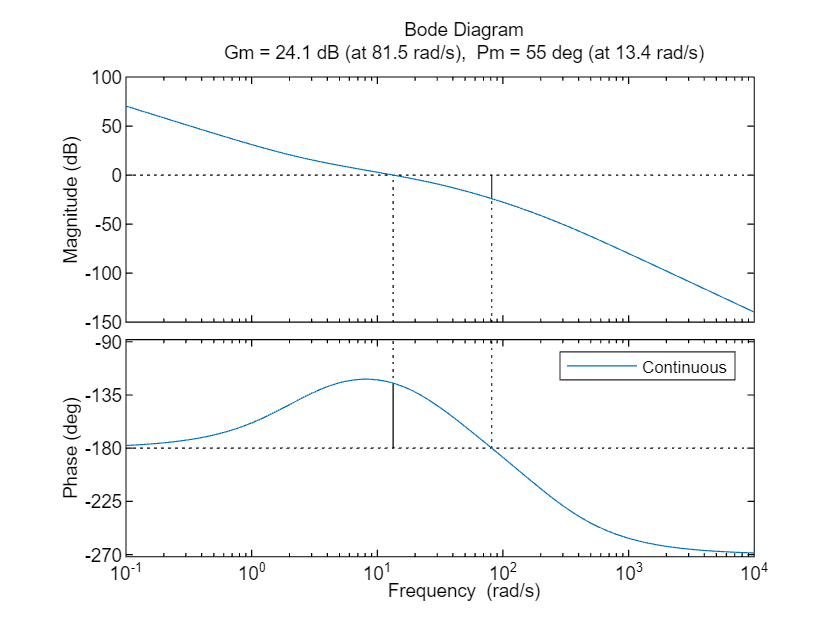

figure;
margin(lead_ctrl_tf*integ_ctrl_tf*plant_tf,bodeoptions);
legend('Continuous');

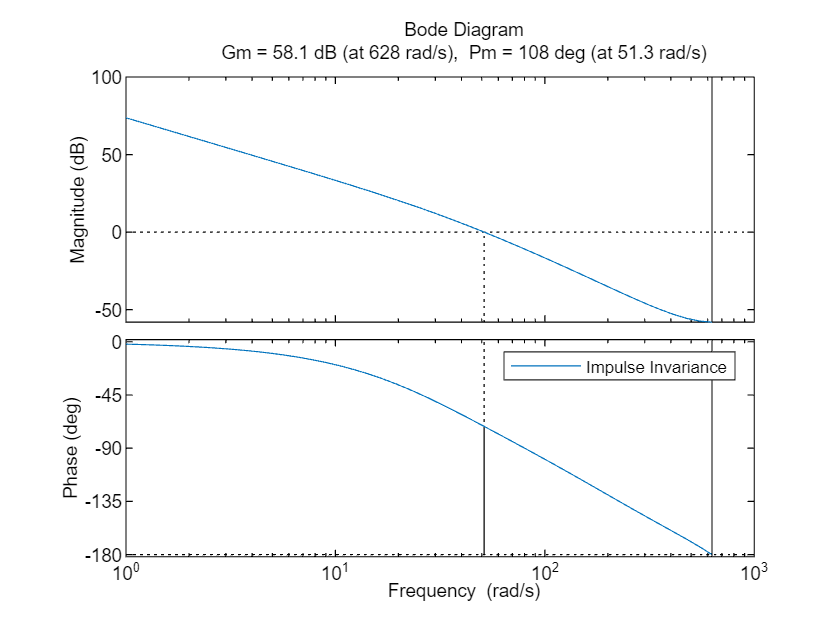

margin(lead_z_iin_neg*intg_z_iin_neg*plant_tf_z,bodeoptions);
legend('Impulse Invariance');

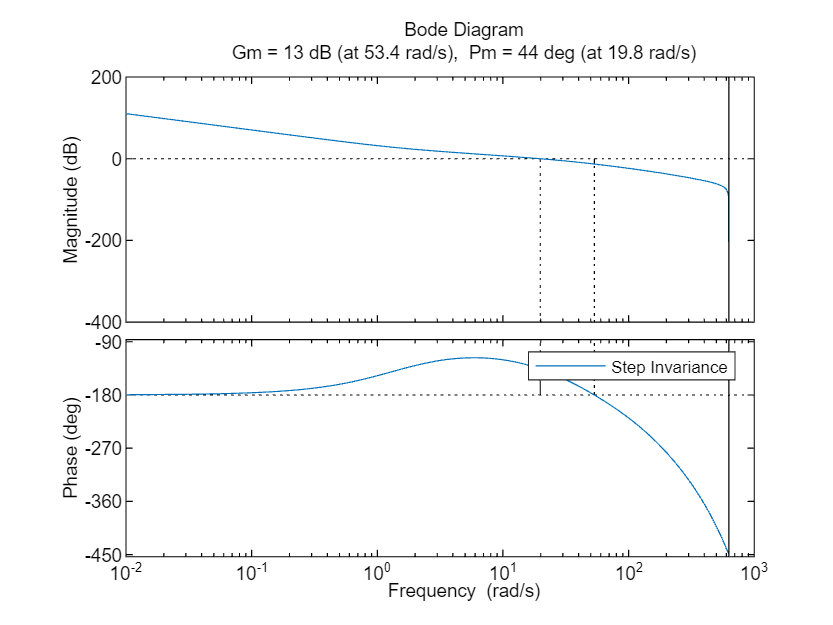

margin(lead_z_zoh_neg*intg_z_zoh_neg*plant_tf_z,bodeoptions);
legend('Step Invariance');

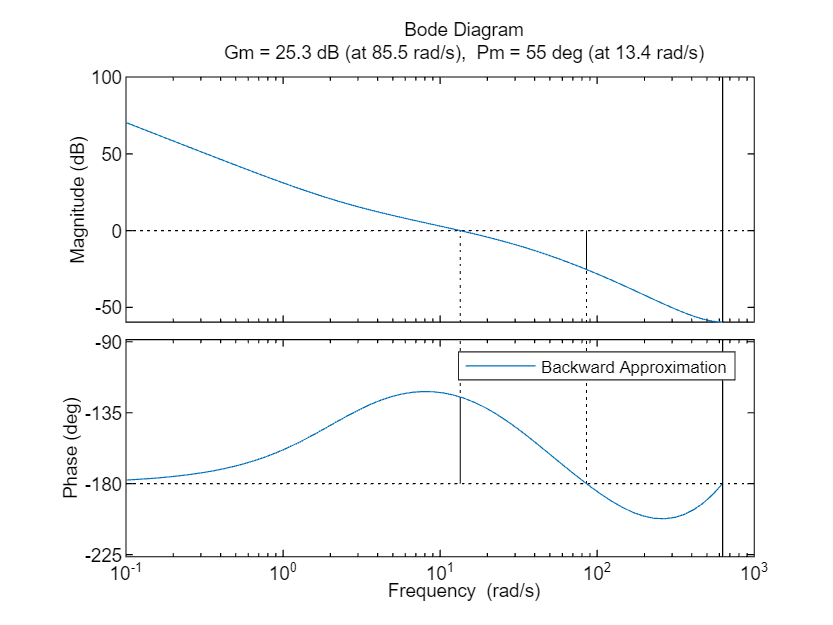

margin(lead_z_bap_neg*intg_z_bap_neg*plant_tf_z,bodeoptions);
legend('Backward Approximation');

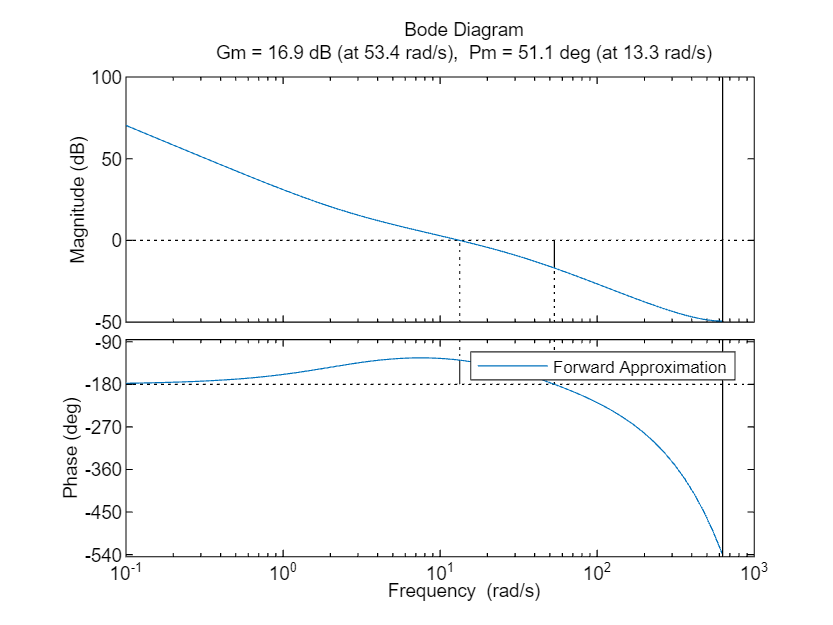

margin(lead_z_fap_neg*intg_z_fap_neg*plant_tf_z,bodeoptions);
legend('Forward Approximation');

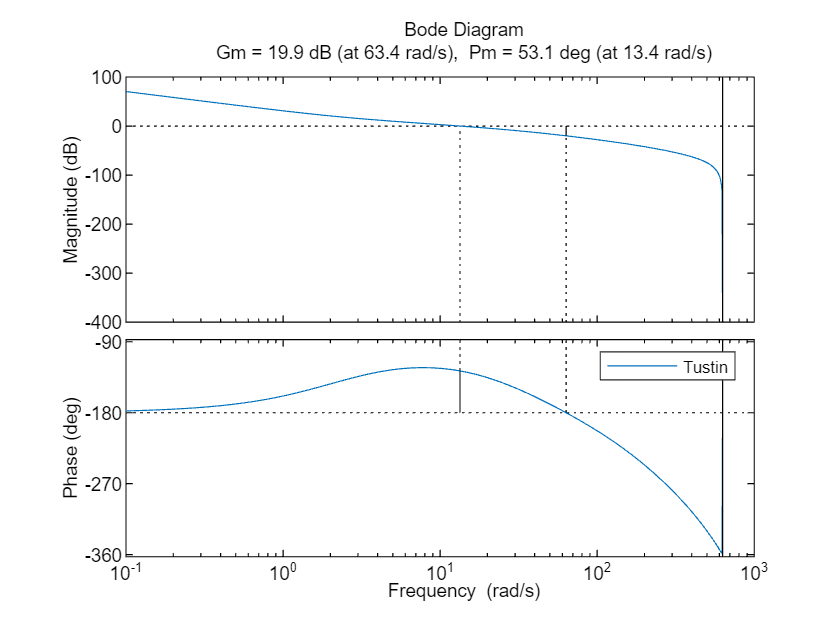

margin(lead_z_tus_neg*intg_z_tus_neg*plant_tf_z,bodeoptions);
legend('Tustin');

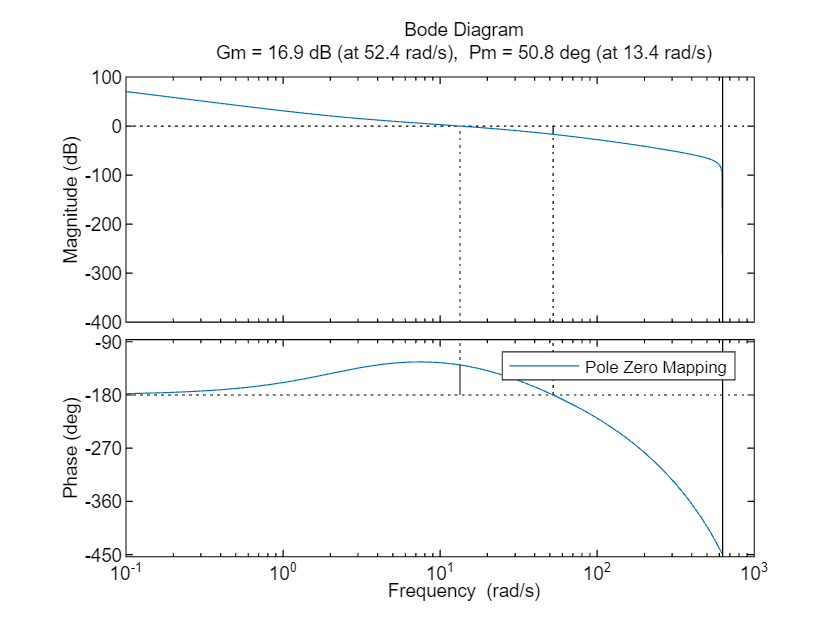

margin(lead_z_pzm_neg*intg_z_pzm_neg*plant_tf_z,bodeoptions);
legend('Pole Zero Mapping');

#### Step Response of Closed Loop for all discretizations

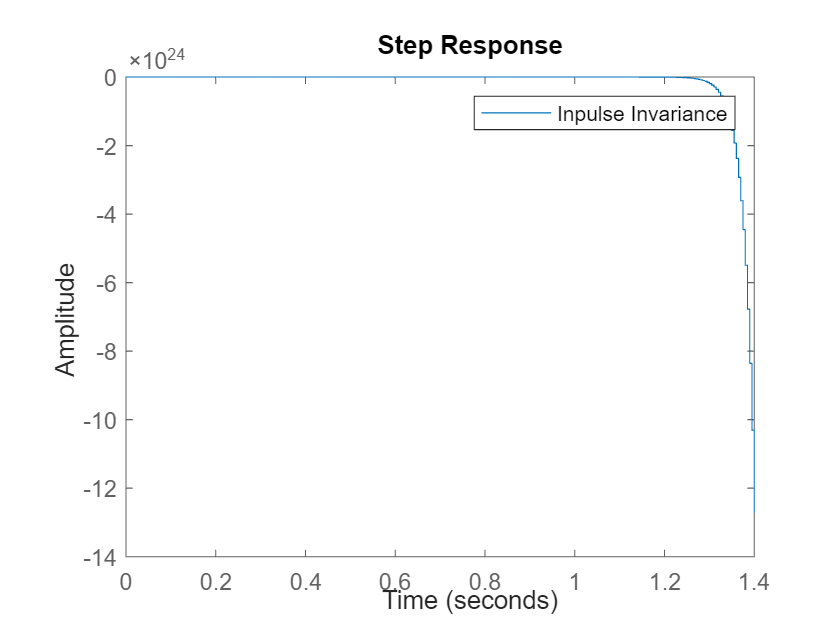

figure
step(feedback(lead_z_iin_neg*intg_z_iin_neg*plant_tf_z,1)); % Unstable
legend('Inpulse Invariance');

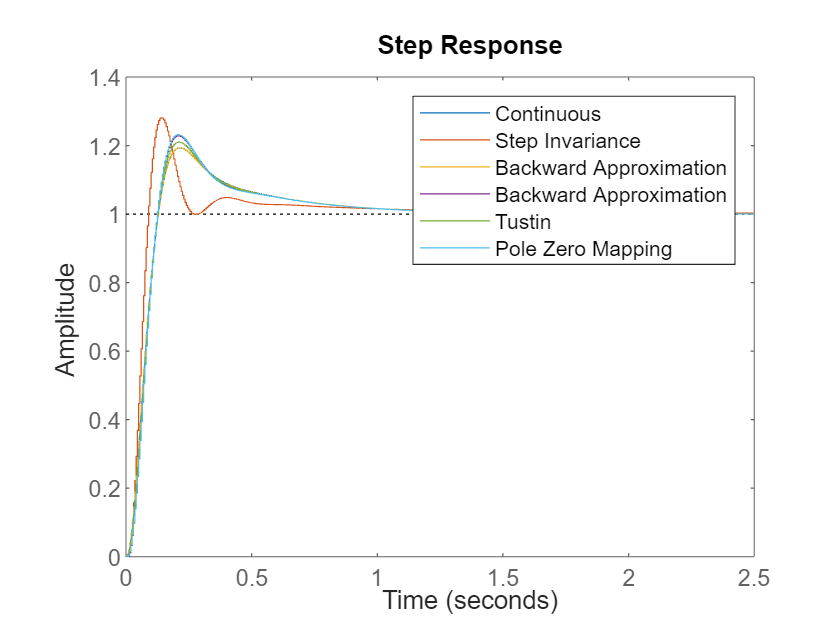

figure
hold on
step(feedback(lead_ctrl_tf*integ_ctrl_tf*plant_tf,1));
step(feedback(lead_z_zoh_neg*intg_z_zoh_neg*plant_tf_z,1));
step(feedback(lead_z_bap_neg*intg_z_bap_neg*plant_tf_z,1));
step(feedback(lead_z_fap_neg*intg_z_fap_neg*plant_tf_z,1));
step(feedback(lead_z_tus_neg*intg_z_tus_neg*plant_tf_z,1));
step(feedback(lead_z_pzm_neg*intg_z_pzm_neg*plant_tf_z,1));
legend('Continuous','Step Invariance','Backward Approximation','Backward Approximation','Tustin','Pole Zero Mapping');

#### Ramp response of Closed Loop for all discretizations

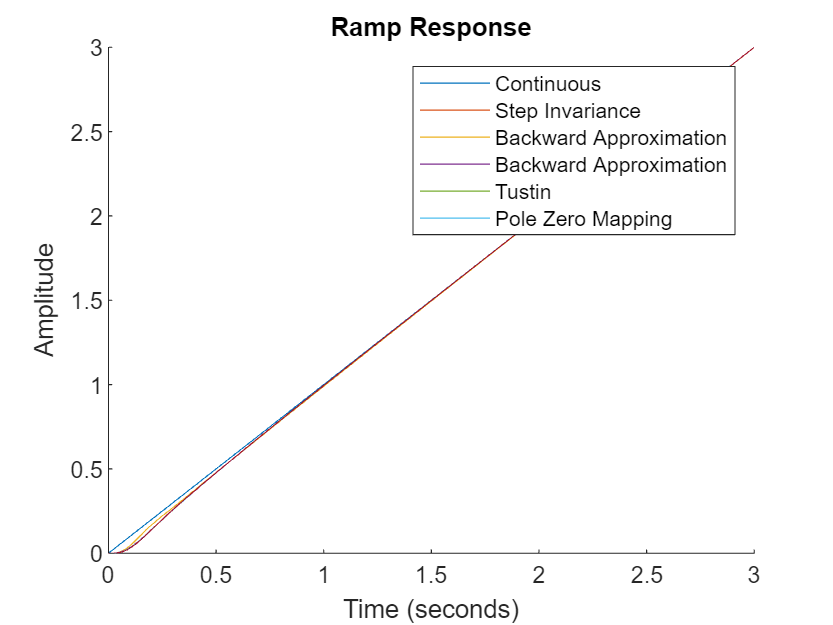

figure
hold on

t=0:0.005:3;
ramp=t;
title('Ramp Response');
xlabel('Time (seconds)');
ylabel('Amplitude');

plot(t,t);
[y,t]=lsim(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1),ramp,t);
plot(t,y);
[y,t]=lsim(feedback(lead_z_zoh_neg*intg_z_zoh_neg*plant_tf_z,1),ramp,t);
plot(t,y);
[y,t]=lsim(feedback(lead_z_bap_neg*intg_z_bap_neg*plant_tf_z,1),ramp,t);
plot(t,y);
[y,t]=lsim(feedback(lead_z_fap_neg*intg_z_fap_neg*plant_tf_z,1),ramp,t);
plot(t,y);
[y,t]=lsim(feedback(lead_z_tus_neg*intg_z_tus_neg*plant_tf_z,1),ramp,t);
plot(t,y);
[y,t]=lsim(feedback(lead_z_pzm_neg*intg_z_pzm_neg*plant_tf_z,1),ramp,t);
plot(t,y);
legend('Continuous','Step Invariance','Backward Approximation','Backward Approximation','Tustin','Pole Zero Mapping');

# Bandwidth Verification

fs=200hz (5ms) must be at least 10 times the bandwidth in closed loop

disp("Impulse Invariance Controller Bandwidth: "     + num2str(bandwidth(feedback(lead_z_iin_neg*intg_z_iin_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Impulse Invariance Controller Bandwidth: 7.0079 Hz


disp("Step Invariance Controller Bandwidth: "        + num2str(bandwidth(feedback(lead_z_zoh_neg*intg_z_zoh_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Step Invariance Controller Bandwidth: 5.7178 Hz


disp("Forward Approximation Controller Bandwidth: "  + num2str(bandwidth(feedback(lead_z_bap_neg*intg_z_bap_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Forward Approximation Controller Bandwidth: 3.649 Hz


disp("Backward Approximation Controller Bandwidth: " + num2str(bandwidth(feedback(lead_z_fap_neg*intg_z_fap_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Backward Approximation Controller Bandwidth: 3.8685 Hz


disp("Tustin Controller Bandwidth: "                 + num2str(bandwidth(feedback(lead_z_tus_neg*intg_z_tus_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Tustin Controller Bandwidth: 3.7552 Hz


disp("Pole Zero Mapping Controller Bandwidth: "      + num2str(bandwidth(feedback(lead_z_pzm_neg*intg_z_pzm_neg*plant_tf_z,1))/(2*pi)) + " Hz");

Pole Zero Mapping Controller Bandwidth: 3.875 Hz


# Comparison with Real Data

time = (0:0.005:8);

#### Square Signal

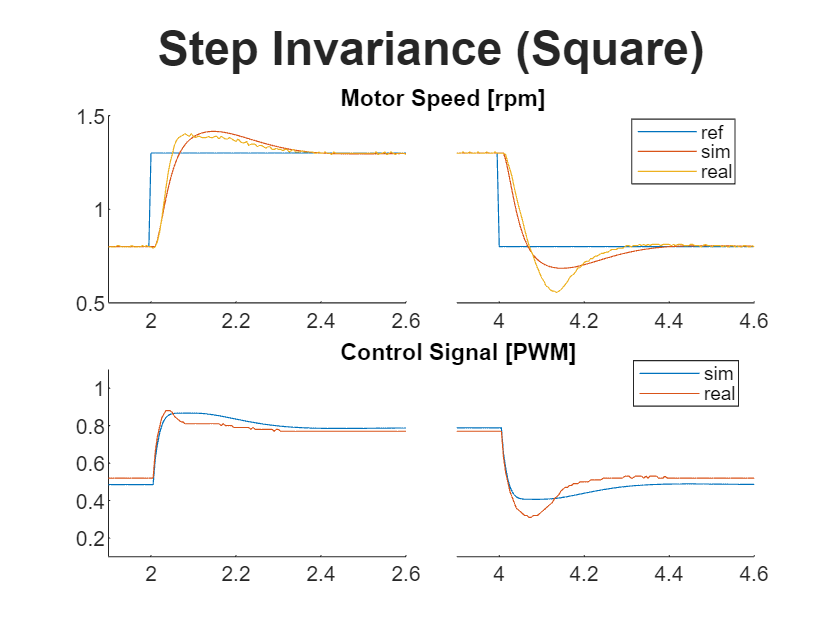

[real_omega_sqr_w, real_u_sqr_w] = data_loader.square_signal_loader('result/lcs_w_sqr.csv',200,4,0.8,1.3);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'Step Invariance (Square)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.lc_w_sqr_ref);
plot(plt1,time, out.lc_w_sqr_omega);
plot(plt1,time, real_omega_sqr_w);
axis(plt1,[1.9 2.6 0.5 1.5]);
title(plt1,'             Motor Speed [rpm]','HorizontalAlignment','left');

plt2=nexttile;
hold on;
plot(plt2,time, out.lc_w_sqr_ref);
plot(plt2,time, out.lc_w_sqr_omega);
plot(plt2,time, real_omega_sqr_w);
axis(plt2,[3.9 4.6 0.5 1.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.lc_w_sqr_u);
plot(plt3,time, real_u_sqr_w);
axis(plt3,[1.9 2.6 0.1 1.1]);
title(plt3,'             Control Signal [PWM]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.lc_w_sqr_u);
plot(plt4,time, real_u_sqr_w);
axis(plt4,[3.9 4.6 0.1 1.1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';

#### Triangle Signal

[real_omega_tri_w, real_u_tri_w] = data_loader.trianglle_signal_loader('result/lcs_w_tri.csv',200,4,0.8,1.3);

Array indices must be positive integers or logical values.

Error in data_loader.square_signal_loader (line 22)
            out=omega(begin_index: end_index +1);

figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'Step Invariance (Triangular)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.lc_w_tri_ref);
plot(plt1,time, out.lc_w_tri_omega);
plot(plt1,time, real_omega_tri_w);
axis(plt1,[1.9 2.6 0.5 1.5]);
title(plt1,'             Motor Speed [rpm]','HorizontalAlignment','left');

plt2=nexttile;
hold on;
plot(plt2,time, out.lc_w_tri_ref);
plot(plt2,time, out.lc_w_tri_omega);
plot(plt2,time, real_omega_tri_w);
axis(plt2,[3.9 4.6 0.5 1.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.lc_w_tri_u);
plot(plt3,time, real_u_tri_w);
axis(plt3,[1.9 2.6 0.1 1.1]);
title(plt3,'             Control Signal [PWM]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.lc_w_tri_u);
plot(plt4,time, real_u_tri_w);
axis(plt4,[3.9 4.6 0.1 1.1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';